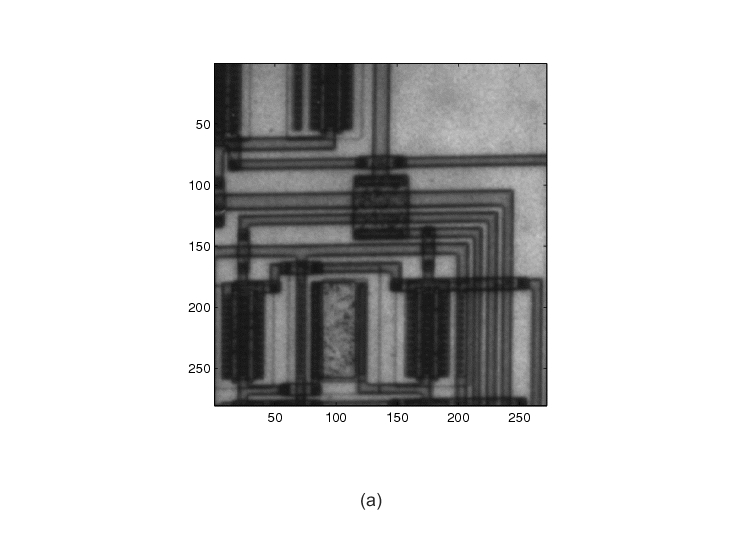


% 19/11/19
% Task 2 test
clear all;
close all;
clc;

% img = imread('spine.jpg');
% img = imread('lighhouse.png');
img = imread('circuit1.bmp');
% img = imread('cameraman.jpg');
% img = imread('peppers.png');
imshow(img);
xlabel('(a)')

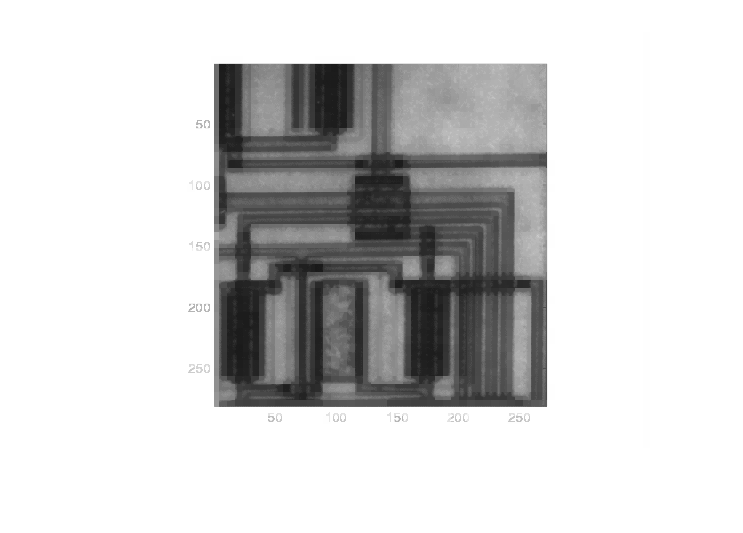


[zipped, info] = diff_coder(img);
x = diff_decoder(zipped, info);
imshow(x);

psnr(x, img)

ans = 23.4218

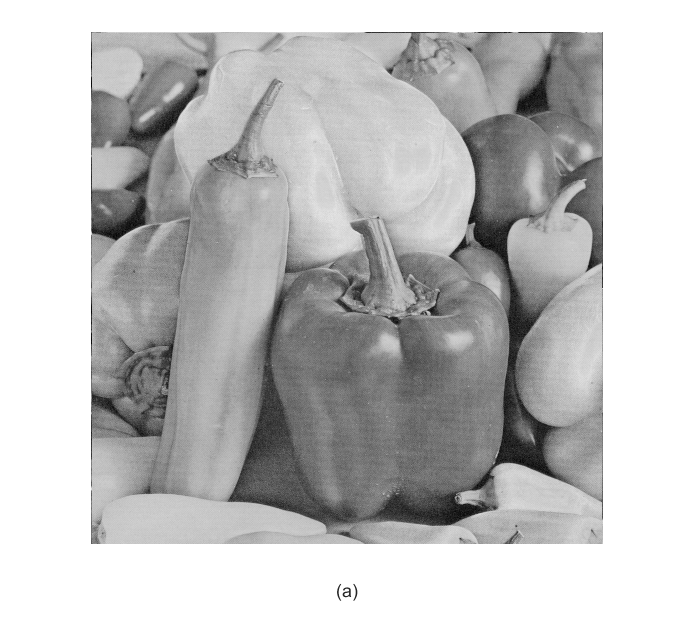

% Task 1 test
clear all;
close all;
clc;

% img = imread('spine.jpg');
% img = imread('lighhouse.png');
% img = imread('circuit1.bmp');
% img = imread('cameraman.jpg');
img = imread('peppers.png');
imshow(img);
xlabel('(a)')

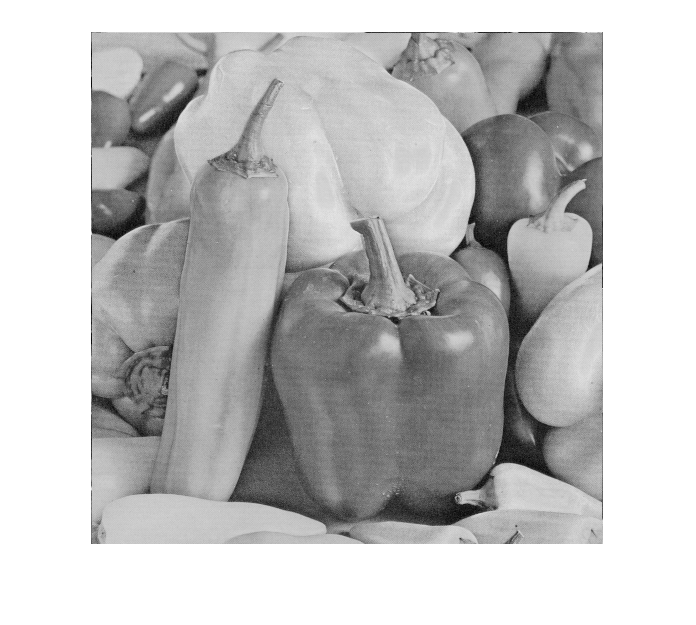


[zipped, info] = pixel_coder(img);
x = pixel_decoder(zipped, info);
imshow(x)


psnr(x, img)

ans = Inf

% DCT2 test robustness.
clear all;
close all;
clc;

img = imread('cameraman.jpg');
[size_row, size_column] = size(img);
fun_dct = @(block_struct) dct2(block_struct.data);
dct_coefficient_diff_img = blockproc(img, [8 8], fun_dct);

% My method
diff_image_dct_matrix = zeros(size_row, size_column);
block_temp = zeros(8,8);
for n = 1:4096
    index_row = ceil(n/64);
    index_column = rem(n,64);
    %     Check whether a block is at the end of current row.
    if(index_column == 0)
        index_column = 64;
    end
    block_temp = img(8*(index_row-1)+1:8*index_row, 8*(index_column-1)+1:8*index_column);
   diff_image_dct_matrix(8*(index_row-1)+1:8*index_row, 8*(index_column-1)+1:8*index_column) = dct_88(block_temp);
end

% Task 3 test
clear all;
close all;
clc;

% img = imread('spine.jpg');
% img = imread('lighhouse.png');
% img = imread('circuit1.bmp');
% img = imread('cameraman.jpg');
img = imread('peppers.png');
imshow(img);
xlabel('(a)')

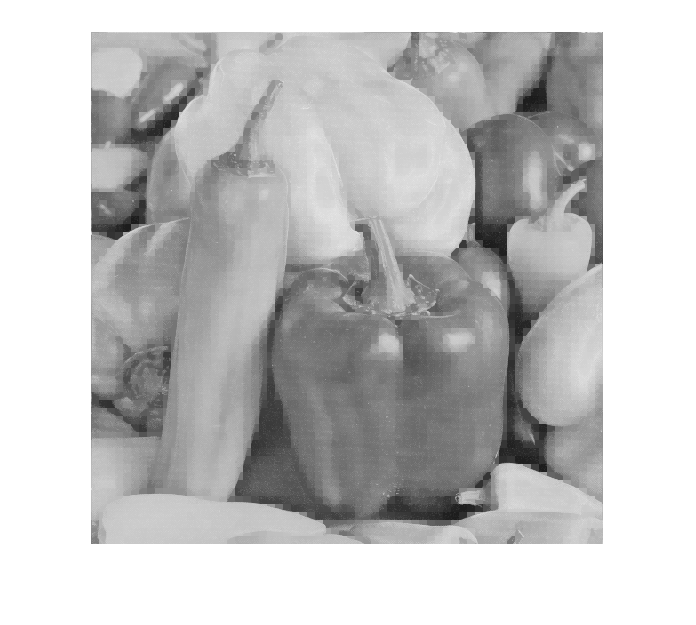


[zipped, info] = jpeg_lite(img);
x = jpeg_lite_decoder(zipped, info);
imshow(x)

psnr(x, img)

ans = 26.7917

clear all;
close all;
clc;
img = imread('cameraman.jpg');

[zipped, info] = norm2huff(img);
x = huff2norm(zipped, info);
[zipped_2, info_2] = norm2huff(reshape(img, [1, 512*512]));
x_2 = huff2norm(zipped_2, info_2);


function res = dct_88(x)
res = dct2(x);
end